# Problem 22.17

clear, constants

k =      8.99e+09

e0 =      8.85e-12

e =     1.602e-19

syms theta q1 phi q2 real
assume(q2 ~= 0)
R = 0.6

R =           0.6

Electric field at the origin due to bead 1 and 2

E1 = k*q1/R^2*[-cos(theta) -sin(theta)]

$$E1 = \left(\begin{array}{cc} -\frac{224750000000\,q_{1}\,\cos\left(\theta \right)}{9} & -\frac{224750000000\,q_{1}\,\sin\left(\theta \right)}{9} \end{array}\right)$$

E2 = k*q2/R^2*[-cos(phi) -sin(phi)]

$$E2 = \left(\begin{array}{cc} -\frac{224750000000\,q_{2}\,\cos\left(\varphi \right)}{9} & -\frac{224750000000\,q_{2}\,\sin\left(\varphi \right)}{9} \end{array}\right)$$

E = E1+E2

$$E = \left(\begin{array}{cc} -\frac{224750000000\,q_{2}\,\cos\left(\varphi \right)}{9}-\frac{224750000000\,q_{1}\,\cos\left(\theta \right)}{9} & -\frac{224750000000\,q_{2}\,\sin\left(\varphi \right)}{9}-\frac{224750000000\,q_{1}\,\sin\left(\theta \right)}{9} \end{array}\right)$$

Ex is zero for $\theta= 90^o$

eq1 = subs(E(1),theta,pi/2) == 0

$$eq1 = -\frac{224750000000\,q_{2}\,\cos\left(\varphi \right)}{9}=0$$

$E_x = -5\times 10^4 N/C$ for $\theta=0$

eq2 = subs(E(1),theta,0) == -5e4

$$eq2 = -\frac{224750000000\,q_{1}}{9}-\frac{224750000000\,q_{2}\,\cos\left(\varphi \right)}{9}=-50000$$

$E_y = -9\times 10^4 N/C$ for $\theta= 90^o$

eq3 = subs(E(2),theta,pi/2) == -9e4

$$eq3 = -\frac{224750000000\,q_{1}}{9}-\frac{224750000000\,q_{2}\,\sin\left(\varphi \right)}{9}=-90000$$

Solve three equations simultaneoulsy yielding two sets of answers

sol = solve([eq1,eq2,eq3],[q1,q2,phi])

sol = struct with fields:
     q1: [2×1 sym]
     q2: [2×1 sym]
    phi: [2×1 sym]

vpa(sol.q1,3)

$$ans = \left(\begin{array}{c} 2.0e-6\\ 2.0e-6 \end{array}\right)$$

vpa(sol.q2,3)

$$ans = \left(\begin{array}{c} -1.6e-6\\ 1.6e-6 \end{array}\right)$$

vpa(sol.phi*180/pi,3)

$$ans = \left(\begin{array}{c} -90.0\\ 90.0 \end{array}\right)$$

Verification by reproducing Figure 22-44 (b) and (c)

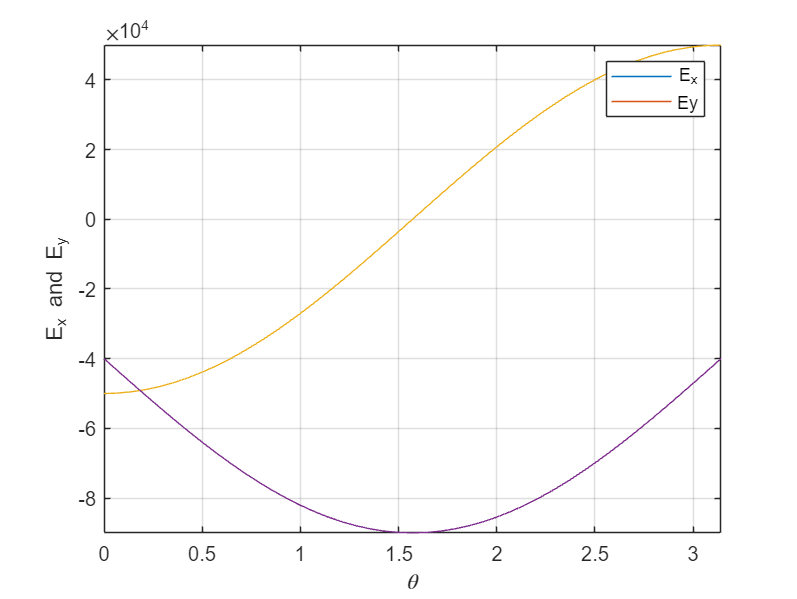

Ex1 = subs(E(1),[q1,q2,phi],[sol.q1(1),sol.q2(1),sol.phi(1)]);
Ey1 = subs(E(2),[q1,q2,phi],[sol.q1(1),sol.q2(1),sol.phi(1)]);
Ex2 = subs(E(1),[q1,q2,phi],[sol.q1(2),sol.q2(2),sol.phi(2)]);
Ey2 = subs(E(2),[q1,q2,phi],[sol.q1(2),sol.q2(2),sol.phi(2)]);
fplot([Ex1 Ey1 Ex2 Ey2],[0 pi]), legend('E_x','Ey'), grid on
xlabel('\theta'), ylabel('E_x and E_y')